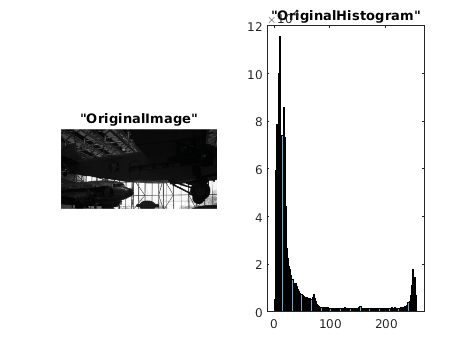

% ORIGINAL IMAGE
I = imread("airplanes.png");
figure
subplot(1,2,1); imshow(I); title "OriginalImage"
subplot(1,2,2); histogram(I); title "OriginalHistogram"

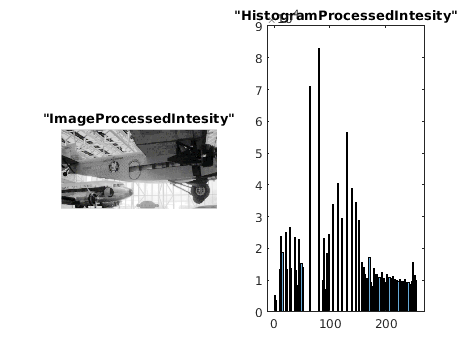

% NEW IMAGE WITH EQUALIZED HISTOGRAM
mapProcessedIntesity = histogramEqualization(I,256);
imageProcessedIntesity = mappingImage(I,mapProcessedIntesity);

figure
subplot(1,2,1); imshow(imageProcessedIntesity); title "ImageProcessedIntesity"
subplot(1,2,2); histogram(imageProcessedIntesity); title "HistogramProcessedIntesity"

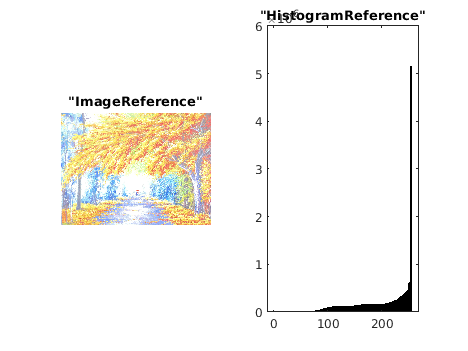

% LOAD IMAGE REFERENCE
Iref = imread("claro.png");

figure
subplot(1,2,1); imshow(Iref); title "ImageReference"
subplot(1,2,2); histogram(Iref); title "HistogramReference"


% GENERATE EQUALIZED HISTOGRAM OF REFERENCE/OBJETIVE
mapRef = histogramEqualization(Iref,256);

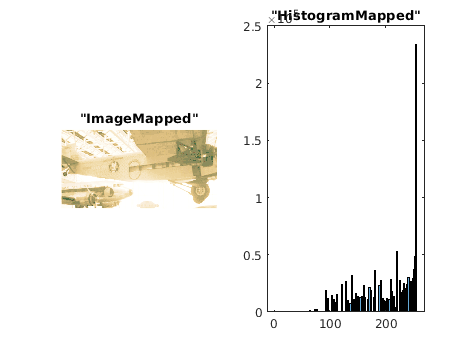

% FUNCTION THAT MAPPED EQUALIZED MAPS
newmap = hitogramMatching(mapProcessedIntesity,mapRef);

% FUNCTION THAT ASSIGN NEW PIXEL VALUE TO THE IMAGE
newimg = mappingImage(I,newmap);

figure
subplot(1,2,1); imshow(newimg); title "ImageMapped"
subplot(1,2,2); histogram(newimg); title "HistogramMapped"

-

function [mapProcessedIntesity] = histogramEqualization(image, imageColorRange)
    
    [sizeY, sizeX, sizeZ] = size(image);

    mapProcessedIntesity = zeros(imageColorRange,sizeZ);

    for i=1:sizeZ

        band = image(:,:,i);
        [count, ~] = imhist(band,imageColorRange);
        processedIntesity = 0;
        
        for j=1:imageColorRange
            processedIntesity = processedIntesity + ((imageColorRange - 1)/(sizeY*sizeX))*count(j);
            mapProcessedIntesity(j,i) = round(processedIntesity); 
        end
        
    end

end

-

function [img] = mappingImage(image,map)
    
    [sizeY, sizeX, sizeZ] = size(image);
    
    for z=1:sizeZ
        for y=1:sizeY
            for x=1:sizeX
                image(y,x,z) = map(image(y,x,z) + 1,z);
            end
        end
    end

    img = image;

end

-

function [map] = hitogramMatching(mapImage,mapRef)

    [sizeY,sizeX] = size(mapRef);

    for i=1:sizeX
        for j=1:sizeY
            sk = mapImage(j,i);
            [~,index] = min(abs(sk - mapRef(:,i)));
            mapImage(j,i) = index;
        end
    end

    map = mapImage;
end